# Amplitude Modulation - AM

% Author Name : Atmanand Manoj Gauns
% Affiliation : Roll No.: 201104012
%               Branch : E&TC GCE
%               Year : TE Sem- 5 2021-22 

## Variables :

clear;
fm1 =80; %% first modulating signal frequency
fm2 =120; %% second modulating signal frequency
fc =1000; %% Carrier frequency
fs =20*fc;%% Sampling frequency
endpoint=1;
t =0:1/fs:endpoint; %% Time series index
l = length(t); %% Length of vector t
i=(-l/2:1:l/2-1); %% frequency series index
Vm1=1; %% Peak amplitude of first modulating signal
Vm2=2; %% Peak amplitude of second modulating signal
Vc = 5; %% Peak amplitude of carrier signal


## Modulating and Carrier signal :

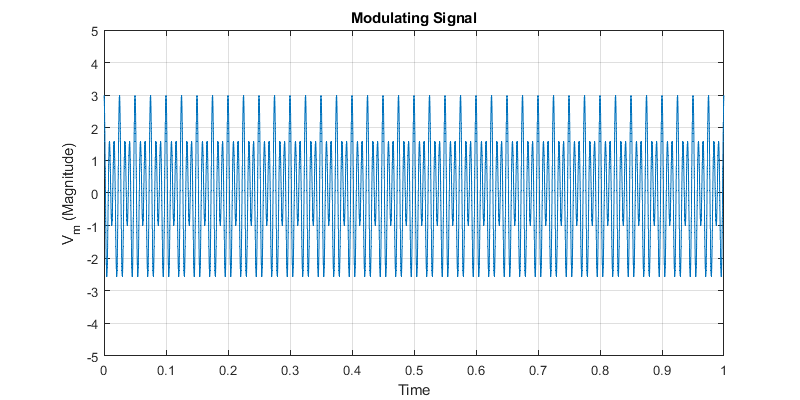

v_m_1 = Vm1 *cos(2*pi*fm1*t);
v_m_2 = Vm2 *cos(2*pi*fm2*t);
v_m=v_m_1+v_m_2; %% multi-tone signal - two-tone signal
f1=figure;
plot(t,v_m);
xlabel("Time");
ylabel("V_m (Magnitude)");
title("Modulating Signal");
set(f1,'Position',[0 0 800 400]);
grid on
ylim([-5.000 5.000]);

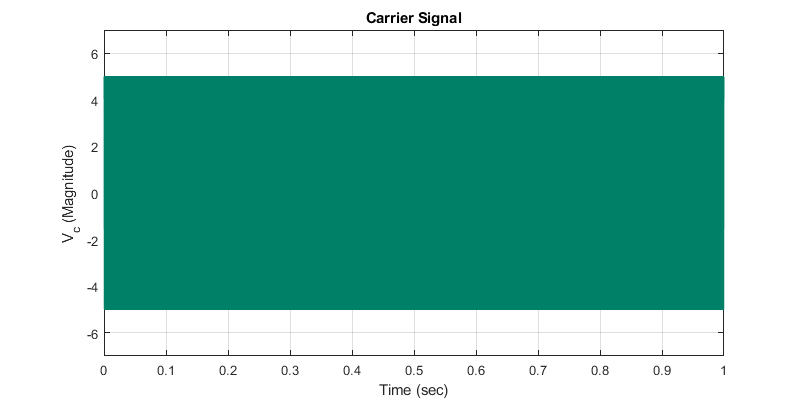

v_c=Vc*cos(2*pi*fc*t ); %%Carrier signal expression
f2 = figure;
set(gcf,'DefaultAxesColorOrder',colormap(summer(2)));
plot(t,v_c);
xlabel("Time (sec)");
ylabel("V_c (Magnitude)");
title("Carrier Signal");
set(f2,'Position',[0 0 800 400]);
grid on;
ylim([-(Vc+2) (Vc+2)]);

## A M Signal :

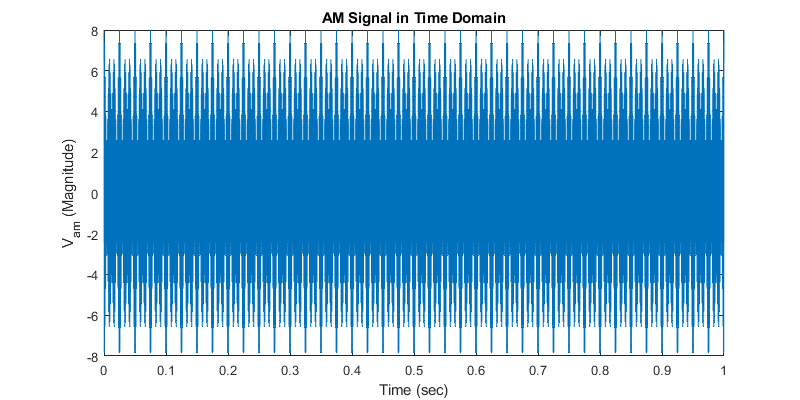

v_am=(Vc+v_m).*cos(2*pi*fc*t);%% multi-tone AM signal - two-tone AM signal
f3=figure;
plot(t,v_am);
xlabel("Time (sec)") ;
ylabel("V_a_m (Magnitude)");
title("AM Signal in Time Domain");
set(f3,'Position',[0 0 800 400]);
grid on;

## A M Spectrum :

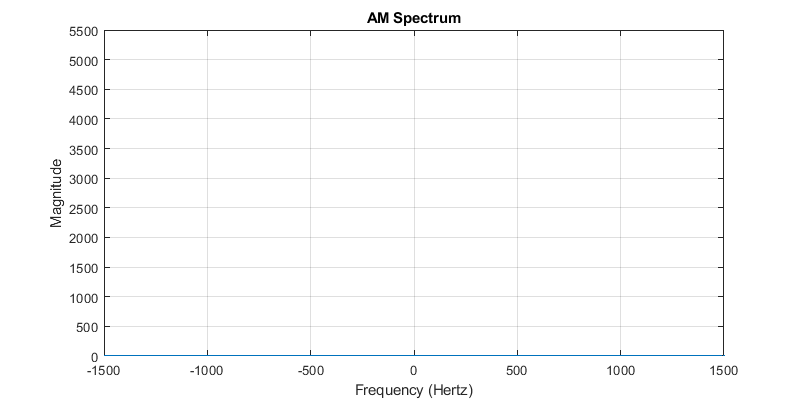

% subplot(3,1,1);
f4=figure;
fftVam=fftshift(fft(v_am));
plot(i*10,abs(fftVam));  %% FFT of AM signal
title("AM Spectrum");
xlabel("Frequency (Hertz)");
ylabel("Magnitude");
set(f4,'Position',[0 0 800 400]);
% xlim([-199 224]);
% ylim([0 5500]);
xlim([-1500 1500]);
ylim([0 5500]);
grid on;

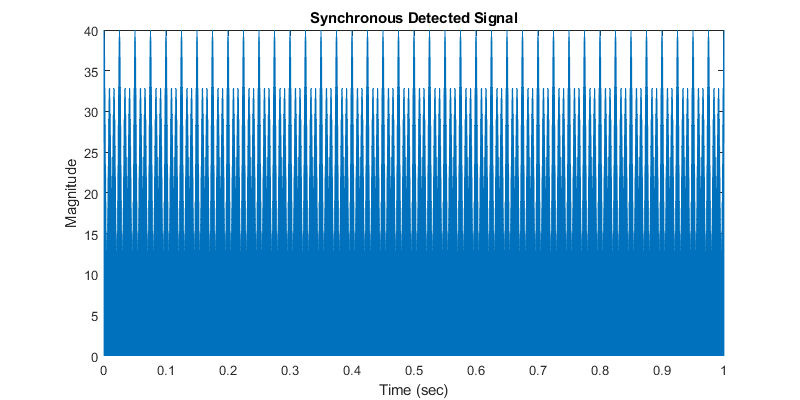

v_m_det=v_am.*v_c; %% Synchronous detection expression
plot(t,v_m_det);
xlabel("Time (sec)") ;
ylabel("Magnitude");
title("Synchronous Detected Signal");

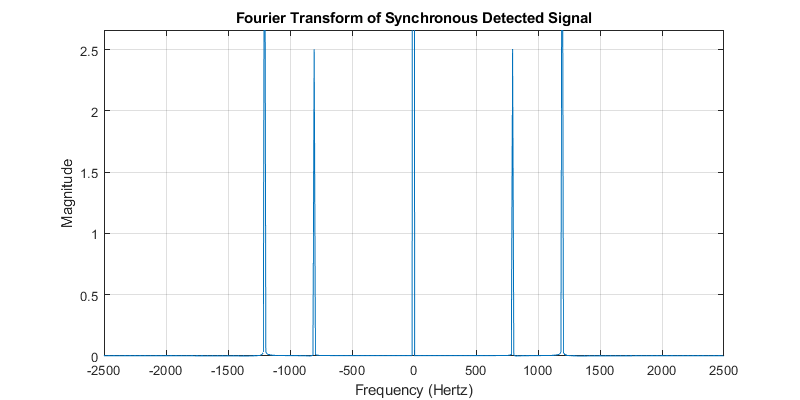

plot(i*10,abs(fftshift(fft(v_m_det)))/10000);
xlabel("Frequency (Hertz)");
ylabel("Magnitude");
title("Fourier Transform of Synchronous Detected Signal");
xlim([-2500 2500]);
ylim([0.00 2.66]);
grid on;

## Low Pass Filter :

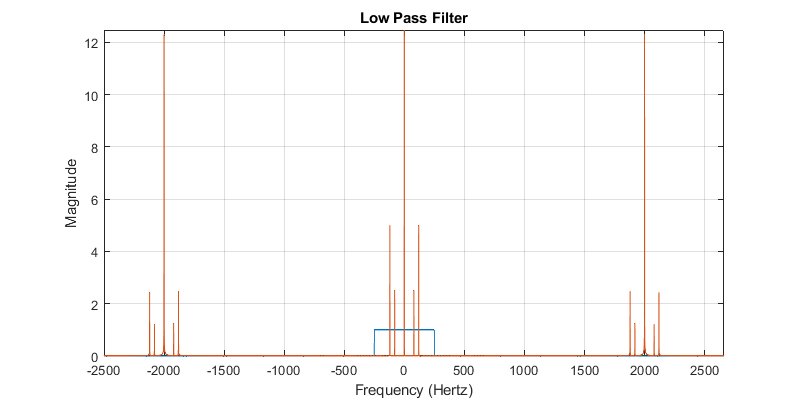


tuner=1500;

a=round(l/2);
b=(2*fc*endpoint-tuner)/2;
lpf=[zeros(1,a-b),ones(1,2*b),zeros(1,l-(2*b+a-b))]; %%LPF response

f6=figure;
plot(i*1,lpf);hold on
plot(i*1,abs(fftshift(fft(v_m_det)))/10000);
xlabel("Frequency (Hertz)");
ylabel("Magnitude");
title("Low Pass Filter");
set(f6,'Position',[0 0 800 400]);
% xlim([-2500 2500]);
% ylim([0.00 2.66]);
grid on;

## Demodulated Signal :

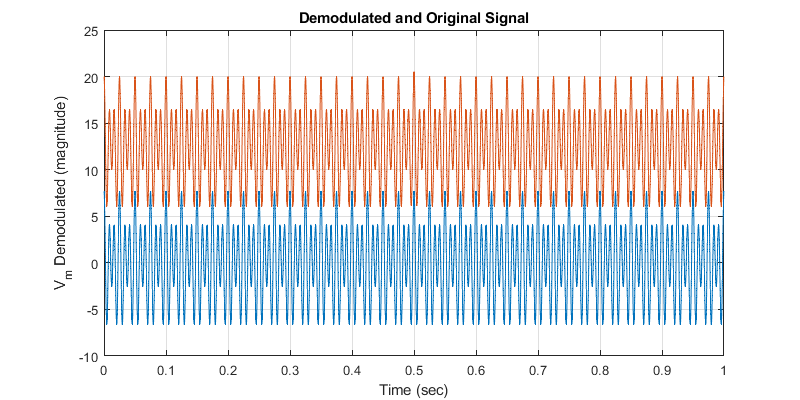

v_m_demod_spec = (fftshift(fft(v_m_det))).*lpf ; %%Frequency domain profile of demodulated signal

f5=figure;
plot(t,v_m*2.569);hold on %% original signal-- blue
% plot(t,-12.504+abs(ifftshift(ifft(v_m_demod_spec))));
plot(t,abs(ifftshift(ifft(v_m_demod_spec)))); %% Final time domain plot of demodulated signal -- orange
xlabel("Time (sec)");
ylabel("V_m Demodulated (magnitude)") ;
title("Demodulated and Original Signal");
set(f5,'Position',[0 0 800 400]);
grid on;